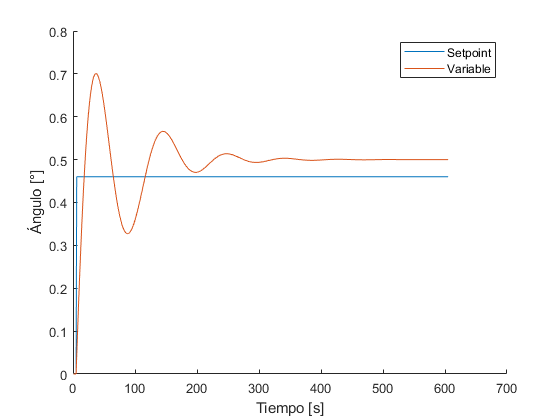

% clear all
load Datos.mat

hold on
x= [0,0,0,0,0,u];
y= [0,0,0,0,0,deseados];
plot(x)
plot(y)

% plot(ControlOutput)
ylabel("Ángulo [°]");
xlabel("Tiempo [s]");
legend("Setpoint","Variable");


% Parte 2
alfa=0.1;
% deseados=0;
Aux=0

Aux = 0



% w=[0.0003,0.0003,0.0000,-0.9441,1.9433];
% entradas=0;
% deseados=0;
randindex=randperm(length(y)-3);
for i=1:length(y)-3
 
 j=randindex(i);
entradas(:,j)=[y(j:j+3)';x(j:j+2)'];
entradas(:,j)=entradas(:,j).*(1+0.00001.*(rand(7,1)-0.5));

deseados(:,j) = x(j+3);
end

ns=size(deseados,1);
no=10;
% w2 = rand(no,size(entradas,1));
% c2 = rand(1,no+1);

[tnEntradas,vEntradas,tEntradas,itnEntradas,ivEntradas,itEntradas] ...
 = dividerand(entradas,1,0,0);
tnDeseados=deseados(:,itnEntradas);
vDeseados=deseados(:,ivEntradas);
tDeseados=deseados(:,itEntradas);

nit=10000;
for i=1:nit
[yrkTn, ecmTrain(:,i),w2,c2] = feedForwardMPerceptron(alfa,tnEntradas,w2,c2,no,tnDeseados,1);

[yrkV, ecmValidacion(:,i)] = feedForwardMPerceptron(alfa,vEntradas,w2,c2,no,vDeseados,0);
% [M,I]=sort(Aux,'descend');
end
[yrkTest, ecmTest] = feedForwardMPerceptron(alfa,vEntradas,w2,c2,no,vDeseados,0);

## Parte 4: Grafico resultados.

fprintf('Graficando errores cuadráticos medio ...\n')

Graficando errores cuadráticos medio ...


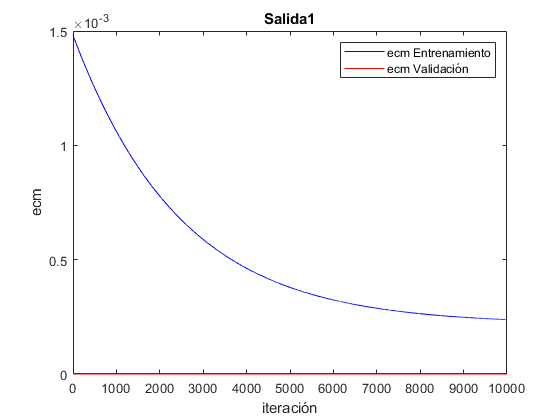

for i = 1:ns
    figure;
    plot(1:nit,ecmTrain(i,:),'b',1:nit,ecmValidacion(i,:),'r');
    xlabel('iteración');
    ylabel('ecm');
    legend('ecm Entrenamiento','ecm Validación')
    title(strcat('Salida ', num2str(i)));
end


fprintf('ECM Para prueba es: %f \n',[ecmTest])

ECM Para prueba es: 0.000000 



save('PesosInverso.mat','w2','c2')